# Temporal slope analysis

Tun this analysis to reproduce slope analysis plts used for the poster.

This is one of the two runme files used to make the poster. The the other for creating figures 1 2 and 3.

Sent this over to javi and kanika via slack; see the google drive file that has information and description about the plots

SUMMARY

So it seems that during the PV task, in both the delta and beta bands the slope deviates from baseline after waking, but only in the control conditions. The slope under blue light is always the same as the slope during presleep. 

During the go nogo task, the slope in the delta band deviates from the baseline slope under BOTH the control and blue light conditions. In the beta band, the slopes never deviate from the presleep slope, neither under control or blue light. That is, sleep inertia with or without blue light has no impact on the slope in the beta band.

The slope of the delta band during the Math has an 'opposite' behavior during the PVT task:  the slope only changes under the blue light, rather than the control condition. the beta band during the math task has some mixed effects: under the control condition, the slope never deviates from presleep slope, but there are two time points under blue light where the slope changes

In all cases where the value of the slope changes -sleep, these changes tend to occur at a time AFTER t = 1. Im not sure what this means, since one  would expect the effects of sleep inertia to be strongest at t = 1.

# THE DATA SET 

%Generate Master Data Set
% First retreive Master Data Set
close all force
cog_task_list = {'PVT', 'GoNogo'};
DF = dfmaster('cogtestlist',cog_task_list);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done

Getting GPSD during GONOGO Task. . . . . . . . . . . . -done

Getting Network Props during GONOGO: . . . . . . . . . . . . -done


# Slope changes during PV Task in beta and delta band under control conditions

**SUMMARY OF FINDINGS**

**Delta Band**

Under control, the slope frequently changes from the pre-sleep slope

(1) note that during control the slope is always significant at all time points. Importantly this is true immediately after waking at t=1, when the effects of sleep inertia should be at their highest.

(2) during control, the slope is significantly different from the pre-sleep slope at all time points except for the second. That is, the slope is steeper during three of the 4 time points after waking

 Under the blue light condition, the slope is for the most part the same as the pre-sleep slope

(1) note that during blue light the slope is always significant at all time points

(2) except for t = 4, the slope under blue light is similar to the slope during pre-sleep. That is, the slope is similar during 3 of the four time points after waking with blue light.

Comments

Most importantly, the changes in slopes occur at t=1 (when the effects of sleep inertia should be at their ) only in the control condition during the PV task. there are no changes under blue light

**Beta Band**

Slope tends to deviate during the control condition

Under the control condition, the slope is always significant

During control condition, the slope becomes steeper 2 out of the 4 time points (@ t=2 and t =3)

Under the Blue Light condition the slope never changes from presleep condition

the slope is always significant

the slope never changes at any time point after pre-sleep

Comments

Most importantly, the changes in slopes occur at t=1 (when the effects of sleep inertia should be at their ) only in the control condition during the PV task. there are no changes under blue light

**General Comments**

in general the slope tends to change from presleep after abrupt awakening under control conditions. This is most obvious in the delta band, which shows a change at  t = 1, where as the beta band deviates at other times and less than the slope of the beta band. Furthermore, the slope under blue light is almost always the same as the pre-sleep slope.

clearvars -except DF; clc
desired_cogtask = 'GoNogo';
close all force
desired_bands = {'delta'};


All Plots

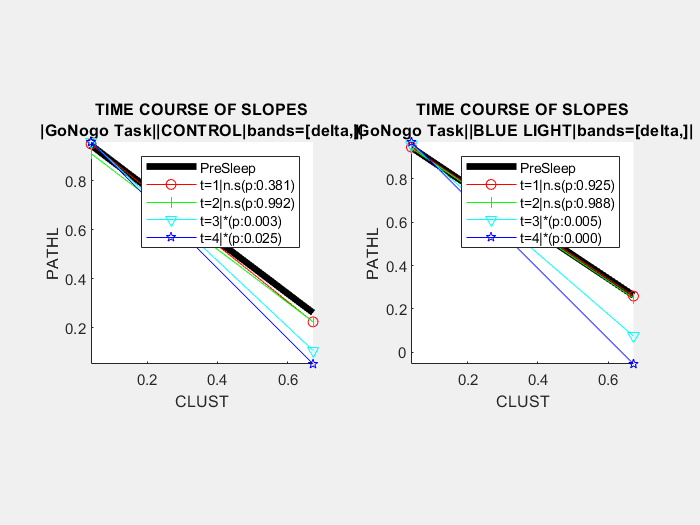

SLOPE @ TIME=[0  1] 
	PreSleep|(r^2:0.989)(b:-1.079)(p:0.000) 
	Control|(r^2:0.989)(b:-1.146)(p:0.000) 
	Blue Light|(r^2:0.954)(b:-1.086)(p:0.000)
 SLOPE DIFFERENCE @ TIME =[0  1] 
	CNTL: (r^2:0.981)(b:-0.068)(p:0.381) 
	LGHT: (r^2:0.981)(b:-0.007)(p:0.925)
SLOPE @ TIME=[0  2] 
	PreSleep|(r^2:0.989)(b:-1.079)(p:0.000) 
	Control|(r^2:0.821)(b:-1.083)(p:0.000) 
	Blue Light|(r^2:0.846)(b:-1.093)(p:0.000)
 SLOPE DIFFERENCE @ TIME =[0  2] 
	CNTL: (r^2:0.834)(b:-0.004)(p:0.992) 
	LGHT: (r^2:0.834)(b:-0.014)(p:0.988)
SLOPE @ TIME=[0  3] 
	PreSleep|(r^2:0.989)(b:-1.079)(p:0.000) 
	Control|(r^2:0.996)(b:-1.343)(p:0.000) 
	Blue Light|(r^2:0.965)(b:-1.397)(p:0.000)
 SLOPE DIFFERENCE @ TIME =[0  3] 
	CNTL: (r^2:0.990)(b:-0.264)(p:0.003) 
	LGHT: (r^2:0.990)(b:-0.319)(p:0.005)
SLOPE @ TIME=[0  4] 
	PreSleep|(r^2:0.989)(b:-1.079)(p:0.000) 
	Control|(r^2:0.920)(b:-1.430)(p:0.000) 
	Blue Light|(r^2:0.985)(b:-1.620)(p:0.000)
 SLOPE DIFFERENCE @ TIME =[0  4] 
	CNTL: (r^2:0.974)(b:-0.351)(p:0.025) 
	LGHT:

figure('Visible', 'On','Name',desired_cogtask);
plotslopetimecourse(DF, desired_cogtask,desired_bands)

Detailed Plots

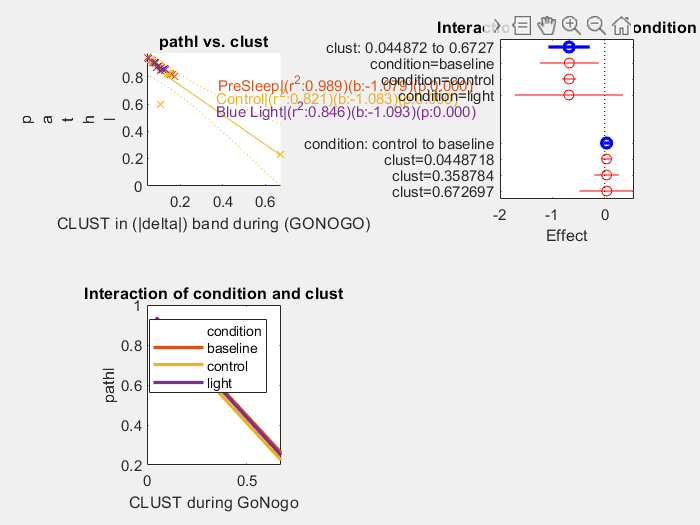

SLOPE @ TIME=[0  2] 
	PreSleep|(r^2:0.989)(b:-1.079)(p:0.000) 
	Control|(r^2:0.821)(b:-1.083)(p:0.000) 
	Blue Light|(r^2:0.846)(b:-1.093)(p:0.000)
 SLOPE DIFFERENCE @ TIME =[0  2] 
	CNTL: (r^2:0.834)(b:-0.004)(p:0.992) 
	LGHT: (r^2:0.834)(b:-0.014)(p:0.988)


t = 2; % try different time points, 1,2,3,4; 
figure('Visible', 'On','Name',sprintf('%s task at t = %d', desired_cogtask, t))
testslopemaster(DF, desired_cogtask,desired_bands,t, display_info = true, runplots_simple = true, runplots_interaction = true, runplots_rawpoints = false); 

# During GoNogo task, slopes changes in DELTA band occur under both blue light and control at a delayed time after waking

**DELTA BAND**

Slopes are always significant in both conditions

During control AND during light, the slope is always significant at all time points 

    - this is the same thig we saw during the PV Task

Slopes become steeper at delayed time points (t=3, and 4) under both control and blue light conditions

this differs from PVT delta band in two ways

- the change in slope occurs at a delayed time point

- slopes change under BOTH blue light and control conditions

**BETA BAND**

Slopes are always significant in both conditions

this is the same in all tasks and bands i have assessed at this point

however there is a monpr exceptopm at t=4 in the control condition, but its almost significant (p=.08)

Slopes never deviate from the presleep slope, neither under blue light, or in control

tfirst time ive seen this 'complete lack' of an effect in neither condition.

clearvars -except DF; clc
desired_cogtask = 'GoNogo';
close all force
desired_bands = {'beta'};


All Plots

figure('Visible', 'On','Name',desired_cogtask);
plotslopetimecourse(DF, desired_cogtask,desired_bands)

Detailed Plots

t = 1; % try different time points, 1,2,3,4; 
figure('Visible', 'On','Name',sprintf('%s task at t = %d', desired_cogtask, t))
testslopemaster(DF, desired_cogtask,desired_bands,t, display_info = true, runplots_simple = true, runplots_interaction = true, runplots_rawpoints = false);     

# Math analysis: Slope changes in DELTA band during the Math task resemble those during the GoNogo task

**DELTA BAND**

Slopes are always significant in both conditions

Note that theres a minor exception at t=1 under the control condition, but the p-value is almost significant

again this is consistent accross tasks

The slopes change at t=2,3 and 4 under under the blue light condition only

this is  similar to what we see during the GONOGO task in the delta band under blue light, except here the slope change occurs at a slightly eralier time point at t = 2

however, this largely contrasts the effects observed during the PVT task in which the changes occured in the control situation

and also differs from the GoNogo task that had dual effects under both conditions

**BETA BAND**

Slopes are always significant in both conditions

again this is consistent accross tasks

The slopes change at t=2,3 and 4 under under the blue light condition only (same exact effects as the delta band)

this differs from the Gonogo because in gonogo beta band  there are never changes in the light, however it is similar because gonogo because there are no changes in the control condition.

again during PVT most of the changes occur under the control condition, unlike we see here

clearvars -except DF; clc
desired_cogtask = 'Math';
close all force
desired_bands = {'beta'};


All Plots

figure('Visible', 'On','Name',desired_cogtask);
plotslopetimecourse(DF, desired_cogtask,desired_bands)

Detailed Plots for a time point

t = 1; % try different time points, 1,2,3,4; 
figure('Visible', 'On','Name',sprintf('%s task at t = %d', desired_cogtask, t))
testslopemaster(DF, desired_cogtask,desired_bands,t, display_info = true, runplots_simple = true, runplots_interaction = true, runplots_rawpoints = false);


# FUNCTION: Get the Grouped Data Frame

function df_grouped = getgroupeddf(DF,  desired_cogtask, desired_band,desired_runs)
    
    if ~ismember(desired_runs,0)
        desired_runs = [0, desired_runs]; % always include baseline
    end

    % Get Band and condition specific Data Frames
    vn = DF.Properties.VariableNames;
    mv = {'chan', 'Y'};
    groupvars =  vn(~ismember(vn,mv));
    df_grouped         = extractdf(DF, desired_cogtask, {'baseline', 'control', 'light'}, desired_band, desired_runs,grouping_vars= groupvars);

end

# FUNCTION: Create new table where clustering and path length are variables

function df_new = extractdf(DF, desired_cogtask, desired_condition, desired_bands, desired_runs, opts)
    arguments
        DF
        desired_cogtask
        desired_condition
        desired_bands
        desired_runs
        opts.grouping_vars = [];
    end
    
    
    % Group by variable
    if isempty(opts.grouping_vars)
        gv = DF.Properties.VariableNames(~ismember(DF.Properties.VariableNames,{'chan', 'Y'}));
    else
        gv = opts.grouping_vars;
    end    

    if ismember('baseline', desired_condition) && not(any(desired_runs==0))
        desired_runs = [0 desired_runs];
    end
    commonrows = @(cogtask, condition, bandnames, runlist)...
        (DF.cogtest == cogtask)...
        & ismember(DF.sbj, goodsbj(cogtask))...
        & any((DF.condition == condition),2)...
        & any(DF.band_ord == bandnames,2)...
        & any(DF.run == runlist,2);

    % Get the data set with the clustering variable 
    df_clust    = DF(commonrows(desired_cogtask, desired_condition,desired_bands, desired_runs)  & DF.ntwprop == 'clust',:);
    df_clust    = varfun(@mean, df_clust, 'InputVariables', "Y", 'GroupingVariables', gv);
    df_clust    = renamevars(df_clust, 'mean_Y', 'Y');
    
    % Get the data set with the path length variable 
    df_pathl    = DF(commonrows(desired_cogtask, desired_condition,desired_bands, desired_runs)  & DF.ntwprop == 'pathl',:);
    df_pathl    = varfun(@mean, df_pathl, 'InputVariables', "Y", 'GroupingVariables', gv);
    df_pathl    = renamevars(df_pathl, 'mean_Y', 'Y');
    
    % Get the data set with the power variable 
    df_gpsd    = DF(commonrows(desired_cogtask, desired_condition,desired_bands, desired_runs)  & DF.ntwprop == 'gpsd',:);
    df_gpsd    = varfun(@mean, df_gpsd, 'InputVariables', "Y", 'GroupingVariables', gv);
    df_gpsd    = renamevars(df_gpsd, 'mean_Y', 'Y');

    % Create Table
    df_new                  = table;
    df_new.clust            = df_clust.Y;
    df_new.pathl            = (df_pathl.Y); % normalize for interpretation
    df_new.gpsd            = (df_gpsd.Y);
   
    df_new.condition        = df_clust.condition;
    

    % Compute percent change      
    if ismember('baseline', desired_condition) 
        getPctChange = @(ntw) (df_new.(ntw)/median(df_new.(ntw)(df_new.condition == 'baseline')) - 1) * 100;
        df_new.clust_dPct = getPctChange('clust') ;
        df_new.pathl_dPct = getPctChange('pathl');
        df_new.gpsd_dPct = getPctChange('gpsd');
        
    end    
    
    if any(ismember(gv, 'band_ord'))
        df_new.band_ord         = df_clust.band_ord;
    end    
    
    
    if any(ismember(gv, 'run'))
        df_new.run    = df_clust.run;
    end

    
    if any(ismember(gv, 'sbj'))
        df_new.sbj              = df_clust.sbj;
    end
    df_new =  dfrmcats(df_new);

end

# FUNCTION: Split and make data frame for each condition

function [df_bl, df_cntl, df_light] = splitgroupeddf(df_grouped)
    arguments
        df_grouped
    end
    % Presleep
    df_bl   = df_grouped(df_grouped.condition == 'baseline',:);

    % Control
    df_cntl = df_grouped(df_grouped.condition == {'control'},:);

    % Light
    df_light    = df_grouped(df_grouped.condition == {'light'},:);   



end

# FUNCTION: Remove Outliers from DF

function df_new = rmoutliers(df,desired_DV,desired_IV ) 
    anoutlier = any(isoutlier([df.(desired_DV), df.(desired_IV)]),2);
    df_new = df(not(anoutlier),:);
end

# ======== TESTING FUNCTIONS

# FUNCTION: Test differences in variances of path length and clustering ===

function [df_grouped] =testdiffinvar(DF,  desired_ntwprop, desired_cogtask, desired_band,desired_runs, ax)
    arguments
        DF,  desired_ntwprop, desired_cogtask, desired_band,desired_runs
        ax.handle = nexttile;
    end
    df_grouped = getgroupeddf(DF,  desired_cogtask, desired_band,desired_runs);

    mnmxrng = groupsummary(df_grouped, "condition",{"min", "max","range"}, desired_ntwprop)   ; 

    min_ntw = ['min_',desired_ntwprop];
    max_ntw = ['max_',desired_ntwprop];
    range_ntw = ['range_',desired_ntwprop];
    mnmxrng = [mnmxrng.(min_ntw), mnmxrng.(max_ntw), mnmxrng.(range_ntw)];

    % Test variance difference in Basleine vs control conditions
    df_bl_v_cntl        = df_grouped(any(df_grouped.condition  == {'baseline','control'},2),:);
    df_bl_v_cntl        = dfrmcats(df_bl_v_cntl);
    p_dvar_bl_vs_cntl   = vartestn(df_bl_v_cntl.(desired_ntwprop), df_bl_v_cntl.condition,'TestType','LeveneAbsolute', 'Display','off');
    
    % test variance difference in baseling vs light condition
    df_bl_v_light   = df_grouped(any(df_grouped.condition  == {'baseline','light'},2),:);
    df_bl_v_light   = dfrmcats(df_bl_v_light);
    p_dvar_bl_vs_light = vartestn(df_bl_v_light.(desired_ntwprop), df_bl_v_light.condition,'TestType','LeveneAbsolute', 'Display','off');
 
    % PLOT
    ax.handle.NextPlot = 'add';   
    boxchart(df_grouped.condition, df_grouped.(desired_ntwprop), 'Orientation','horizontal');
    xlabel(desired_ntwprop)

    % make all plots have the same range
    df_grouped_allruns = getgroupeddf(DF,  desired_cogtask, desired_band,0:4);
    [mn, mx] = bounds(df_grouped_allruns.(desired_ntwprop));
    xlim([mn mx]);

    % Display information as text
    task_info    = sprintf('\n\n%s task |%s|runs: %s \n',desired_cogtask, cell2mat(strcat(desired_band,{','})), num2str(desired_runs));
    testinfo     = sprintf('\nDifferences in %s VARIABILITY between conditions\n\n', upper(desired_ntwprop));  

    dvar_bl_vs_cntl_str  = sprintf('\tBL vs CNTL (p = %.03f)\n', p_dvar_bl_vs_cntl );
    dvar_bl_vs_light_str = sprintf('\tBL vs LIGHT (p = %.03f)\n', p_dvar_bl_vs_light );
    
    var_info     = sprintf('\n[min max range]): \n\t(presleep: %.04f, %.04f, %.04f)\n\t(control: %.04f, %.04f, %.04f))\n\t(light: %.04f, %.04f, %.04f)',...
        mnmxrng(1,1:3), mnmxrng(2,1:3),mnmxrng(3,1:3)  );
    dvar_info    = sprintf('%s %s %s %s %s', task_info, testinfo, dvar_bl_vs_cntl_str,dvar_bl_vs_light_str, var_info);
    text(ax.handle, .1,.9,dvar_info,"FontSize",8,"Units","normalized","HorizontalAlignment","left", 'FontWeight','bold');

    
        

end

# FUNCTIONS TO TEST THE SLOPE

## Combination Test

function [lm_smp, lm_int] = testslopemaster(DF, desired_cogtask,desired_band, desired_run, opts)
    arguments
        DF, desired_cogtask,
        desired_band
        desired_run 
        opts.display_info = false
        opts.runplots_simple = true
        opts.runplots_interaction = true;
        opts.runplots_rawpoints = false;        
    end

    desired_run_vs_bl = [0 desired_run];
    lm_smp = testslope(DF,  desired_cogtask, desired_band,desired_run_vs_bl, runplots = opts.runplots_simple);    
    
    lm_int = testdiffslopes(DF, desired_cogtask, desired_band,desired_run_vs_bl,runplots_interaction = opts.runplots_interaction ,runplots_rawpoints = opts.runplots_rawpoints);

    if opts.display_info
        fprintf('%s %s', lm_smp.all_info,lm_int.all_info)
    end
end

## Test the slope without interaction terms 

function  [LM,df_grouped] = testslope(DF,  desired_cogtask, desired_band,desired_runs,opts)
    arguments
        DF, desired_cogtask, desired_band,desired_runs,
        opts.desired_DV = 'pathl'
        opts.desired_IV = 'clust';
        opts.display_info =  false;
        opts.runplots = true;
    end
    df_grouped = getgroupeddf(DF,  desired_cogtask, desired_band,desired_runs);
    
    % === get data frames
    [df_bl, df_cntl, df_light] = splitgroupeddf(df_grouped);


    % Presleep
    lm_bl   = fitlm(df_bl,'ResponseVar',opts.desired_DV,'PredictorVars',opts.desired_IV);   
    lm_bl_info =sprintf('PreSleep|%s',getlminfo(lm_bl, opts.desired_IV)); 

    % Control   
    lm_cntl = fitlm(df_cntl,'ResponseVar',opts.desired_DV,'PredictorVars',opts.desired_IV);     
    lm_cntl_info =sprintf('Control|%s',getlminfo(lm_cntl, opts.desired_IV));

    % Light

    lm_light    = fitlm(df_light,'ResponseVar',opts.desired_DV,'PredictorVars',opts.desired_IV);    
    lm_light_info =sprintf('Blue Light|%s',getlminfo(lm_light, opts.desired_IV));

    % Plot if desired
    if opts.runplots       
        band_name_str = sprintf('|%s|',lm_bl.VariableInfo.Range{ismember(lm_bl.VariableInfo.Row, 'band_ord')});
        xlabel_str = sprintf('%s in (%s) band during (%s)\n', upper(opts.desired_IV), band_name_str, upper(desired_cogtask));
    
        % plot fit of when wake, both interventions
        ax = nexttile; 
        hold on;    
        ax_plot_bl = lm_bl.plot;
        set(ax_plot_bl, 'Color', condclr('baseline'));
    
        ax_plot_cntl = lm_cntl.plot;
        set(ax_plot_cntl, 'Color', condclr('control'));
    
        ax_plot_light = lm_light.plot;
        set(ax_plot_light, 'Color', condclr('light'));
        
        axis tight
        axis square
    
        % Create Legend 
        ax_lgd = legend('Location','best');
        txtpos = ax_lgd.Position(1:2);
        text(txtpos(1),txtpos(2), lm_bl_info, 'Units','normalized', 'Color',condclr('baseline'), 'FontSize',9);
        text(txtpos(1)-.01,txtpos(2)-.1, lm_cntl_info, 'Units','normalized', 'Color',condclr('control'),'FontSize',9);
        text(txtpos(1)-.01,txtpos(2)-.2, lm_light_info, 'Units','normalized', 'Color',condclr('light'),'FontSize',9);
        delete(ax_lgd);
    
        xlabel(xlabel_str);
        ylabel(opts.desired_DV')
    end
    % Get information about linear models
    LM.bl = lm_bl;
    LM.bl_info = lm_bl_info;
    LM.cntl = lm_cntl;
    LM.cntl_info = lm_cntl_info;
    
    LM.light = lm_light;
    LM.light_info = lm_light_info;    
     
    LM.all_info = sprintf('SLOPE @ TIME=[%s] \n\t%s \n\t%s \n\t%s\n',num2str(desired_runs), LM.bl_info,LM.cntl_info,LM.light_info);
    
    if opts.display_info 
        fprintf(LM.all_info)
    end
end

## Test the slope with an interaction term

function  [lm_int, df_grouped] = testdiffslopes(DF,  desired_cogtask, desired_band,desired_runs, opts)
    arguments
        DF,  desired_cogtask, desired_band,desired_runs
        opts.desired_DV = 'pathl'
        opts.desired_IV = 'clust'
        opts.display_info=false
        opts.runplots_interaction = true;
        opts.runplots_rawpoints = false;
    end
    
    df_grouped = getgroupeddf(DF,  desired_cogtask, desired_band,desired_runs);

    lm = fitlm(df_grouped,"interactions",...
        'ResponseVar',opts.desired_DV,...
        'PredictorVars',{opts.desired_IV,'condition'},...
        'CategoricalVars',{'condition'});   
    
    % plot the interaction effects
    if opts.runplots_interaction 
        nexttile
        plotInteraction(lm, opts.desired_IV, 'condition')
    
        nexttile
        plotInteraction(lm, 'condition', opts.desired_IV,'predictions');
    
        xlabel(sprintf('%s during %s', upper(opts.desired_IV), desired_cogtask));
        ylabel(opts.desired_DV)
    end

    % Plot a scatter plot to see the raw data points
    if opts.runplots_rawpoints
        nexttile; hold on;
        blidx   = lm.Variables.condition == 'baseline';
        cntl_idx = lm.Variables.condition == 'control';
        light_idx = lm.Variables.condition == 'light';
    
        x = lm.Variables.(opts.desired_IV);
        y = lm.Variables.(opts.desired_DV);
        scatter(x(blidx), y(blidx),'filled', 'MarkerFaceColor',condclr('baseline'));
        scatter(x(cntl_idx), y(cntl_idx),'filled','MarkerFaceColor',condclr('control'));
        scatter(x(light_idx), y(light_idx),'filled','MarkerFaceColor',condclr('light'));    
        
        xlabel(sprintf('%s during %s', upper(opts.desired_IV), desired_cogtask));
        ylabel(upper(opts.desired_DV))
    end

    % save model information
    lm_int.lm = lm;
    lm_cntl_int_info = getlminfo(lm , sprintf('%s:condition_control',opts.desired_IV));
    lm_light_int_info = getlminfo(lm , sprintf('%s:condition_light',opts.desired_IV));    
    lm_int.all_info = sprintf('SLOPE DIFFERENCE @ TIME =[%s] \n\tCNTL: %s \n\tLGHT: %s\n',num2str(desired_runs), lm_cntl_int_info, lm_light_int_info ) ;
    
    if opts.display_info
        disp(lm_int.all_info )
    end
     
end

## plot slopes accross time

function plotslopetimecourse(DF, desired_cogtask,desired_bands)

    lm = testdiffslopes(DF, desired_cogtask, desired_bands,1:4,runplots_interaction = false ,runplots_rawpoints = false);
    lm = lm.lm;
    yvarname = lm.ResponseName;
    xvarname = lm.PredictorNames{not(ismember(lm.PredictorNames,'condition'))};
    [xbounds] = lm.VariableInfo.Range { ismember(lm.VariableInfo.Row, xvarname)};

    writetitle = @(condition) sprintf('TIME COURSE OF SLOPES\n|%s Task||%s|bands=[%s]|', desired_cogtask, condition, sprintf('%s,',desired_bands{:}));
    ax_cntl = nexttile; 
    ax_cntl.NextPlot = "add";
    ax_cntl.Title.String = writetitle('CONTROL');

    ax_light = nexttile;
    ax_light.Title.String = writetitle('BLUE LIGHT');
    ax_light.NextPlot = "add";


    colorset = {'r', 'g', 'c', 'b'};
    markerset = {'o', '|', 'v', 'p'};  

    
     
     for t = 1:4

        [lm_simp, lm_int] = testslopemaster(DF, desired_cogtask,desired_bands,t,...
            display_info = true,runplots_simple = false, runplots_interaction = false, runplots_rawpoints = false);  
        
        if t == 1
            lm =  lm_simp.bl;
            line(ax_cntl, xbounds, feval(lm,xbounds),'Color', 'k', 'LineWidth', 4);
            issig_cntl = {'PreSleep'};

            line(ax_light, xbounds, feval(lm,xbounds),'Color', 'k','LineWidth', 4);
            issig_light = {'PreSleep'};
            
        end           

        lm =  lm_simp.cntl;
        issig_cntl = [issig_cntl, sprintf('t=%d|%s',t,getlminfo(lm_int.lm, 'clust:condition_control', statname = 'issig'))];          
        line(ax_cntl, xbounds, feval(lm,xbounds),'Color', colorset{t}, 'Marker', markerset{t})    ;        


        lm =  lm_simp.light;        
        issig_light = [issig_light, sprintf('t=%d|%s',t,getlminfo(lm_int.lm, 'clust:condition_light', statname = 'issig'))];  
        
        line(ax_light, xbounds, feval(lm,xbounds),'Color', colorset{t}, 'Marker', markerset{t});        

        
    end
    legend(ax_light, issig_light);
    legend(ax_cntl, issig_cntl);

    [ymin, ymax] = bounds([ax_light.YLim ax_cntl.YLim]);
    set(ax_light, 'Ylim',[ymin ymax], 'Xlim', xbounds);
    set(ax_cntl, 'Ylim',[ymin ymax],'Xlim', xbounds);
    
    axis(ax_light, 'square','tight');
    axis(ax_cntl, 'square','tight');

    xlabel(ax_light, upper(xvarname));
    ylabel(ax_light, upper(yvarname));
    xlabel(ax_cntl, upper(xvarname));
    ylabel(ax_cntl, upper(yvarname));        
    
    figure(gcf)

end

# FUNCTION: get lm info ===

function lminfo = getlminfo(lm, coeffname, opts)
    arguments
        lm
        coeffname
        opts.statname = 'all';
    end
    coeff_val = lm.Coefficients.Estimate(ismember(lm.Coefficients.Row, coeffname));
    coeff_pval = lm.Coefficients.pValue(ismember(lm.Coefficients.Row, coeffname));

    rsqr_val = lm.Rsquared.Adjusted;
    switch opts.statname 
        case 'all'
        lminfo = sprintf('(r^2:%.03f)(b:%.03f)(p:%.03f)',rsqr_val, coeff_val, coeff_pval);   
        case 'issig'
            if coeff_pval < .05
                lminfo = sprintf('*(p:%.03f)',coeff_pval);
            else
                lminfo = sprintf('n.s(p:%.03f)',coeff_pval);                
            end
            

    end
end

function drawcolor = condclr(condition)
    switch condition
        case 'baseline'
            drawcolor = [0.8500    0.3250    0.0980];
        case {'control', 'cntl'}
            drawcolor=[0.9290    0.6940    0.1250];
        case {'light'}
            drawcolor = [0.4940    0.1840    0.5560];
        otherwise
            error('LUIS: unkown experiment condition')

    end

end

# THEORY

% (Hilditch et al., 2021, p. 14)
% cognitive functions are associated with different oscillatory
% schemes,21,30,31 where
% - slower frequencies have been associated
%     - with top-down processes like executive actions and attention,32,33
%
% - higher frequencies are associated with
%     - motor control or maintenance of sensorimotor behaviors,34
%         
% - and even higher frequencies with
%     - localized, specific, and rapid computations.35”
% 
% - Sleep like properties of waking brain (vs rested wakefulness)
%     - increased delta power over posterior regions of the brain,10,11
%     - reduced beta power across all brain regions,11
%     - and increased functional connectivity of the default mode
%     network.12